# Which file type is best for what?

n_rows= 10^3;
n_cols = 2;

n_chars= 10^2;
s = RandStream('mlfg6331_64'); 


%TODO make data into a matrix
%data = randsample(s,10,n_rows,true)
data = char(randi([33 126],n_rows,n_chars));
my_table = table(string(data));


data_to_write = table2array(my_table);


### Write data to files

.csv

tic
writetable(my_table,"data/dat.csv")
csv_write_time = toc;

.Parquet

tic
parquetwrite("data/dat.parquet", my_table)
parquet_write_time =toc;

.H5

tic
h5filename = "data/dat.h5";
if exist(h5filename)
    delete(h5filename)
end

h5create(h5filename, "/table", size(data_to_write),"Datatype","string")
h5write(h5filename, "/table", data_to_write)

h5_write_time = toc;
%h5disp(h5filename)


.NC

tic
filename = "data/dat.nc";
if exist(filename)
    delete(filename)
end


nccreate(filename, "table", "Dimensions",{"table", length(data_to_write)}, 'Datatype', "string", 'Format', 'netcdf4')
ncwrite(filename, "table", data_to_write)

nc_write_time =toc;
%ncdisp(filename)



## Read timing

.csv

tic
readtable("data/dat.csv");
csv_read_time = toc;

.parquet

tic
parquetread("data/dat.parquet");
parquet_read_time = toc;


.h5

tic
h5read("data/dat.h5","/table");
h5_read_time = toc;

.nc

tic
ncread("data/dat.nc","table");
nc_read_time = toc;

## Agreggate Performance Statistics

[i]= dir("data/dat*");i_table=struct2table(i);
result_table =i_table(:, ["name", "bytes"]);
write_times = [csv_write_time, h5_write_time, nc_write_time, parquet_write_time]';
read_times = [csv_read_time, h5_read_time, nc_read_time, parquet_read_time]';
result_table.write_time = write_times;
result_table.read_time = read_times;

result_table

result_table = 4×4 table
         name            bytes       write_time    read_time
    _______________    __________    __________    _________

    {'dat.csv'    }    1.0404e+05     0.15799       0.39093 
    {'dat.h5'     }    1.4822e+05     0.11438      0.020695 
    {'dat.nc'     }    1.5322e+05     0.21474      0.033937 
    {'dat.parquet'}     1.064e+05       0.119       0.22799 


input_data = my_table;

generate_stats(input_data)

ans = 4×4 table
         name            bytes       write_time    read_time
    _______________    __________    __________    _________

    {'dat.csv'    }    1.0404e+05      0.13987      0.32181 
    {'dat.h5'     }    1.4822e+05     0.098041     0.005325 
    {'dat.nc'     }    1.5322e+05      0.13785     0.005199 
    {'dat.parquet'}     1.064e+05     0.067743      0.16517 


2^18

ans = 262144

h5_size =[];
csv_size=[];
parquet_size=[];
nc_size=[];
num_rows = [];
for i=1 : 18
    n_rows= 2^i;
    t=generate_stats(generate_table(n_rows,3));

    csv_size  = [ csv_size,   t.bytes(1)] ;
    h5_size  = [ h5_size,   t.bytes(2)] ;
    nc_size  = [ nc_size,   t.bytes(3)] ;
    parquet_size = [parquet_size, t.bytes(4)];

    num_rows = [num_rows, n_rows];
end

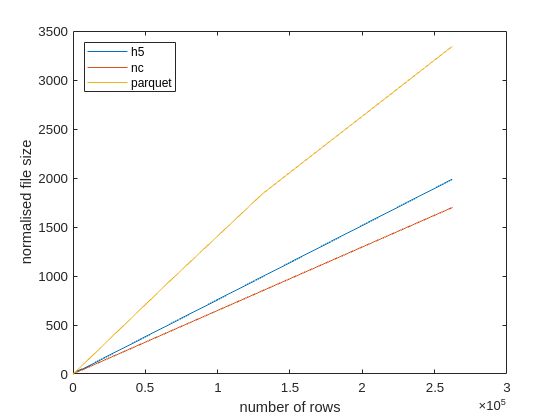


plot(num_rows, h5_size./ h5_size(1), "DisplayName","h5")
hold on
%plot(num_cols, csv_size ./ csv_size(1), "DisplayName","csv")
plot(num_rows, nc_size ./ nc_size(1), "DisplayName","nc")
plot(num_rows, parquet_size ./ parquet_size(1), "DisplayName","parquet")

hold off
legend("Location","northwest")
xlabel('number of rows')
ylabel("normalised file size")

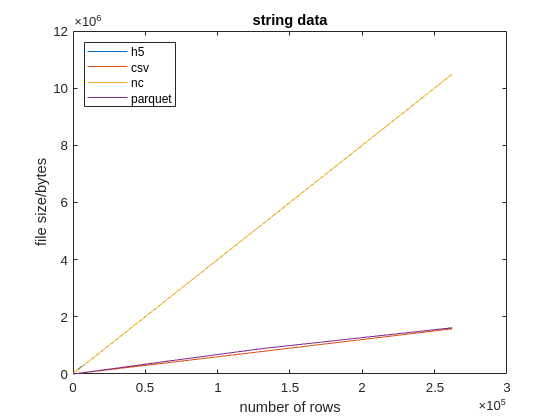

plot(num_rows, h5_size, "DisplayName","h5")
hold on
plot(num_rows, csv_size , "DisplayName","csv")
plot(num_rows, nc_size, "DisplayName","nc")
plot(num_rows, parquet_size , "DisplayName","parquet")

hold off
legend("Location","northwest")
xlabel('number of rows')
ylabel("file size/bytes")
title( "string data")

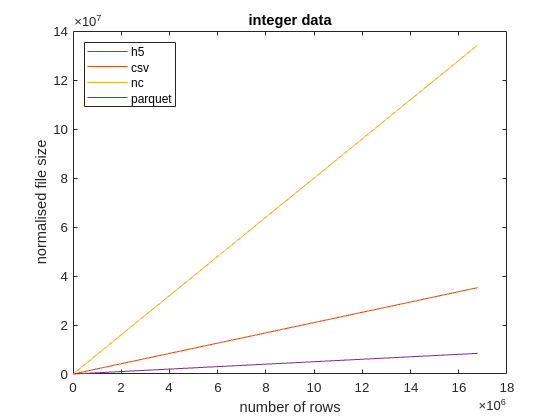

h5_size =[];
csv_size=[];
parquet_size=[];
nc_size=[];
num_rows = [];
for i=1 : 24
    n_rows= 2^i;
    t=generate_stats_int(generate_int_table(n_rows));

    csv_size  = [ csv_size,   t.bytes(1)] ;
    h5_size  = [ h5_size,   t.bytes(2)] ;
    nc_size  = [ nc_size,   t.bytes(3)] ;
    parquet_size = [parquet_size, t.bytes(4)];

    num_rows = [num_rows, n_rows];
end

plot(num_rows, h5_size, "DisplayName","h5")
hold on
plot(num_rows, csv_size , "DisplayName","csv")
plot(num_rows, nc_size, "DisplayName","nc")
plot(num_rows, parquet_size , "DisplayName","parquet")

hold off
legend("Location","northwest")
xlabel('number of rows')
ylabel("normalised file size")
title('integer data')

randi([0, 9], [4,6])

ans =      9     8
     8     1
     3     1
     7     1
     9     5
     7     8
     3     1
     9     8
     2     9
     1     6


function [output_table]= generate_table(n_rows,n_chars)

data = char(randi([33 126],n_rows,n_chars));
output_table = table(string(data));
end

function [output_table]= generate_int_table(n_rows)
s = RandStream('mlfg6331_64'); 
data = randsample(s,10,n_rows,true);
output_table = table(data);
end
